# 三次样条插值法

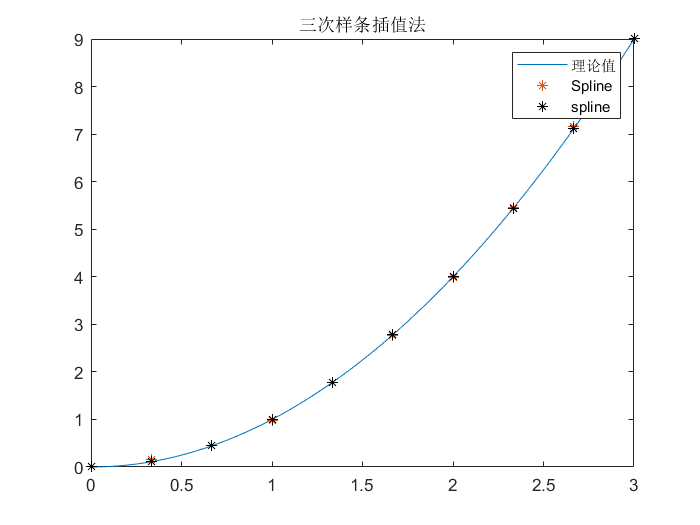

clear;clc;
x = linspace(0, 3, 5);
y = x.^2;
xi = linspace(0, 3, 10);
yi1= Spline(x, y, xi);
yi2 = spline(x, y, xi);
xx = linspace(0, 3, 100);
yy = xx.^2;
plot(xx, yy, xi, yi1, '*', xi, yi2, 'k*');
legend('理论值', 'Spline', 'spline');
title('三次样条插值法');

function yy = Spline(x, y, xx)
%{
函数功能：三次样条插值法；
输入：
  x：已知点横坐标；
  y：已知点纵坐标；
  xx：插值点；
输出：
  yy：插值点的函数值；
%} 
% = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = 
n = length(x);
a = y(1 : end - 1);
b = zeros(n - 1, 1);
d = zeros(n - 1, 1);
dx = diff(x);
dy = diff(y);
A = zeros(n);
B = zeros(n, 1);
% 自然样条端点条件：端点二阶导数为零
A(1, 1) = 1;
A(n, n) = 1;
for i = 2 : n - 1
    A(i, i - 1) = dx(i - 1);
    A(i, i) = 2*(dx(i - 1) + dx(i));
    A(i, i + 1) = dx(i);
    B(i) = 3*(dy(i) / dx(i) - dy(i - 1) / dx(i - 1));
end
c = A \ B;
for i = 1 : n - 1
    d(i) = (c(i + 1) - c(i)) / (3 * dx(i));
    b(i) = dy(i) / dx(i) - dx(i)*(2*c(i) + c(i + 1)) / 3;
end
m = length(xx);
yy = zeros(m, 1);
for i = 1 : m
    for ii = 1 : n - 1
        if xx(i) >= x(ii) && xx(i) < x(ii + 1)
            j = ii;
            break;
        elseif xx(i) == x(n)
            j = n - 1;
        end
    end
    yy(i) = a(j) + b(j)*(xx(i) - x(j)) + c(j)*(xx(i) - x(j))^2 + d(j)*(xx(i) - x(j))^3;
end
end